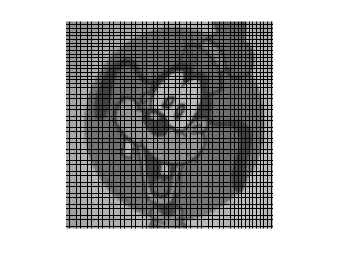

clc;clear all
dog=im2gray(imread('goofy.png'));
for i=1:length(dog)
    if mod(i,5)==0
        dog(:,i)=0;
        dog(i,:)=0;
    end
end
imshow(dog)

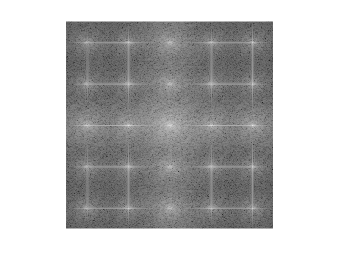

dof=fftshift(fft2(dog));
fftshow(dof)

fii=ones(282);
fii(:,18:38)=0;
fii(18:38,1:142)=0;
fii(:,75:95)=0;
fii(70:90,1:142)=0;
fii(130:150,1:120)=0;
fii(240:260,1:142)=0;
fii(180:200,1:142)=0;
fii(1:120,132:152)=0;
fii(162:282,132:152)=0;
%fftshow(dof.*fii)
%imshow(log(1+abs(ifft2(dof.*fii,'symmetric'))/255))


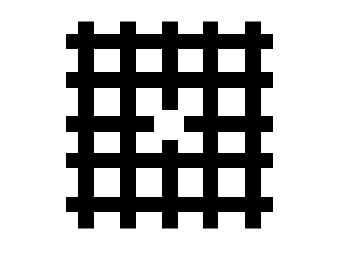

fii(:,245:265)=0;
fii(:,187:207)=0;
fii(18:38,:)=0;
fii(70:90,:)=0;
fii(240:260,:)=0;
fii(180:200,:)=0;
fii(130:150,162:282)=0;
imshow(fii)

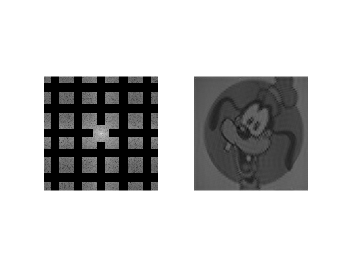

subplot(121)
fftshow(dof.*fii)
subplot(122)
imshow(log(1+abs(ifft2(dof.*fii,'symmetric'))/255))